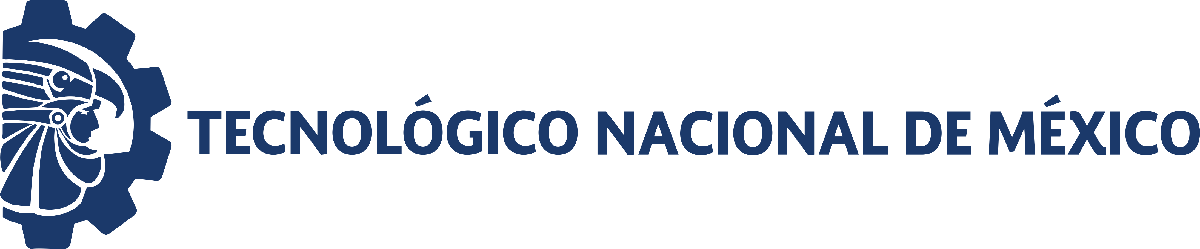                                 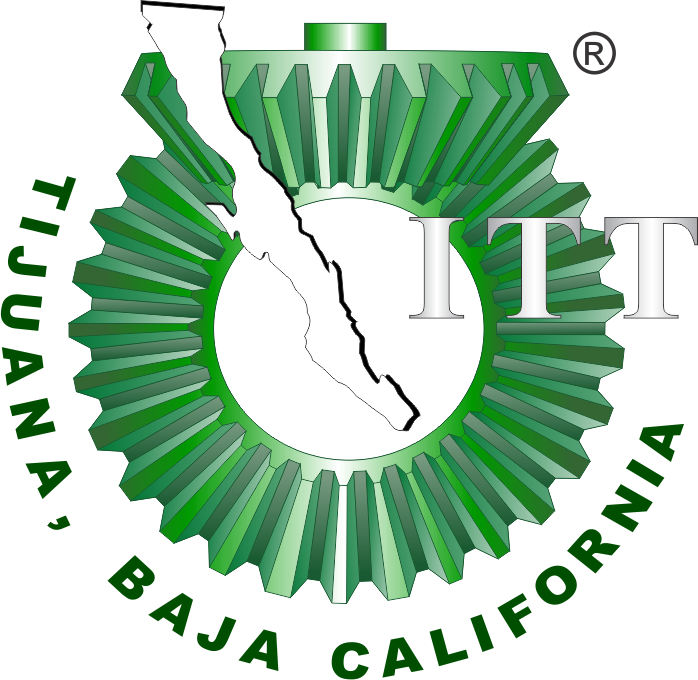

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[FOTO]

Nombre del alumno: Carlos Daniel Frausto Luna

Número de control: C18210366

Correo institucional: carlos.frausto18**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all') 
tend = '10';
file = 'sistema2023a';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta al escalón

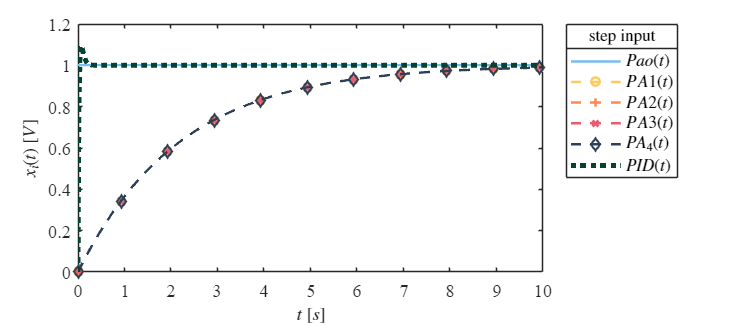

signal = 'step';
set_param('sistema2023a/S1','sw','1');
set_param('sistema2023a/Pao(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Pao,x1.PA1,x1.PA2,x1.PA3,x1.PA4,x1.PID,signal)

## Respuesta al impulso

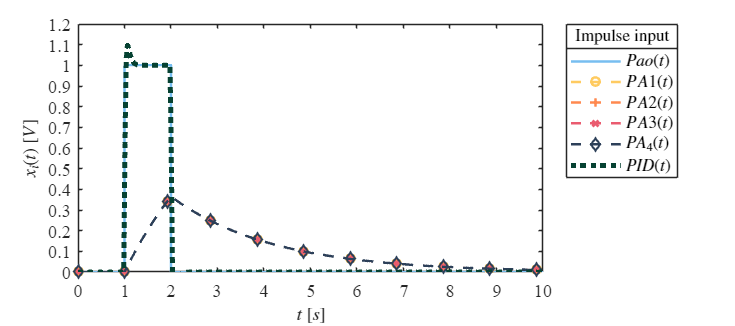

signal = 'Impulse';
set_param('sistema2023a/S1','sw','0');
set_param('sistema2023a/Pao(t)','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Pao,x2.PA1,x2.PA2,x2.PA3,x2.PA4,x2.PID,signal)

## Respuesta a la rampa

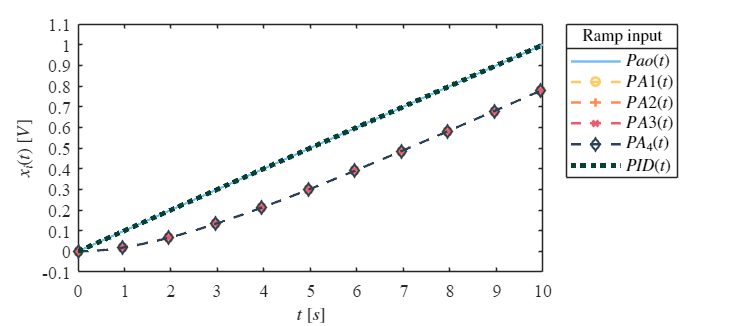

signal = 'Ramp';
set_param('sistema2023a/S2','sw','1');
set_param('sistema2023a/Pao(t)','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Pao,x3.PA1,x3.PA2,x3.PA3,x3.PA4,x3.PID,signal)

## Respuesta a la función sinusoidal

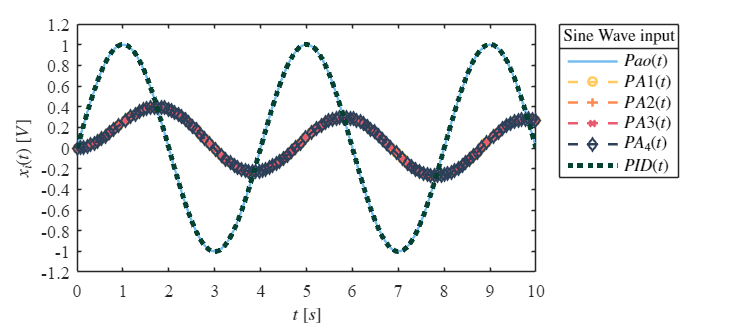

signal = 'Sine Wave';
set_param('sistema2023a/S2','sw','0');
set_param('sistema2023a/Pao(t)','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Pao,x4.PA1,x4.PA2,x4.PA3,x4.PA4,x4.PID,signal)

## Funcion: respuesta a las señales

function plotsignals(t,Pao,PA1,PA2,PA3,PA4,PID,signal)

    t   = t(:);
    Pao = Pao(:);
    PA1 = PA1(:);
    PA2 = PA2(:);
    PA3 = PA3(:);
    PA4 = PA4(:);

    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50;]/255;
    colororder(mycolors)

    p= plot(t,Pao,'-',t,PA1,'--O',t,PA2,'--+',t,PA3,'--x',t,PA4,'--d',t,PID,':', ...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(6),'LineWidth',3);
    L= legend('$P{ao}(t)$','$P{A1}(t)$','$P{A2}(t)$','$P{A3}(t)$','$P{A_4}(t)$','${PID}(t)$');
    set(L,'interpreter','latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','latex','FontSize',11 )

    xlim([0,10]); xticks(0:1:10);
    if signal == "Step" || signal =="Impulse"
            ylim([0,1.2]); yticks(0:0.1:1.2);
    elseif signal == "Ramp"
            ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1);
    elseif signal == "Sine Wave"
            ylim([-1.2,1.2]); yticks(-1.2:0.2:2);
    end 
    exportgraphics(gcf,[signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[signal,'.png'],'ContentType','vector')
end